# 
$$gpr !/10:,\text{ } gc$$


gs = cell(2,10); tc = nrt;
for r = 1:2
    for col = 1:2:10
        tic
        gs{r,col} = fitrgp(tc{r,col}, ... % gprMdl1
            tc{r,col}.Properties.VariableNames{...
            end}, 'Sigma',.002);
        gs{r,col+1} = fitrgp(tc{r,col}, ... % gprM2
            tc{r,col}.Properties.VariableNames{...
            end}, 'KernelFunction',...
            'ardsquaredexponential',...
              'FitMethod','sr','PredictMethod', ...
              'fic','Standardize',1,'Sigma',.002);
        fprintf([num2str([(col+1)/2 toc]) ' s\n']);
    end
end
[num2str(fix(toc/60)) ': ' num2str(rem(toc, 60) ...
    ) 's']
gs

# Latitude gpr:

% rng('default')
gs = cell(2,10); t = tic;
for r = 1:2
    for col = 1:2:10
        tic
        gs{r,col} = fitrgp(tc{r,col}, ... % gprMdl1
            tc{r,col}.Properties.VariableNames{...
            end}, 'Sigma',.002);
        gs{r,col+1} = fitrgp(tc{r,col}, ... % gprM2
            tc{r,col}.Properties.VariableNames{...
            end}, 'KernelFunction',...
            'ardsquaredexponential',...
              'FitMethod','sr','PredictMethod', ...
              'fic','Standardize',1,'Sigma',.002);
        fprintf([num2str([(col+1)/2 toc]) ' s\n']);
    end
end
toc(t)
% gt = gs

# gpr: x10^

% c
nt = nrt; gn = cell(2,2); tic
for r = 1:2
    gn{r,1} = fitrgp(nt{r,1}, ... % gprMdll1
    nt{r,1}.Properties.VariableNames{end},...
    'Sigma',.002);
    gn{r,2} = fitrgp(nt{r,1}, ... % gprMdll2
    nt{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
end
toc

Elapsed time is 12.213120 seconds.


gn

gn = 2x2 cell array
    {1x1 RegressionGP}    {1x1 RegressionGP}
    {1x1 RegressionGP}    {1x1 RegressionGP}


## 
$$SNR$$


nt = cell(2,2);
for r = 1:2
    nt{r,1} = c{r,1};
    for k = 2:10
        nt{r,1} = [nt{r,1};
                   c{r,k}];
    end
    t = nt{r,1};
    if r == 1
        n = t; sh = 60; % 70;
        kh = t(:, 1).Variables;
        ka = t(:, 2).Variables; snr = 55; % sh
        o = t(:, 3).Variables; so = snr+20; %-20+20
        n(:,1).Variables =awgn(kh,sh,'measured');
        % nt(:,1).Variables = ntla(:, 1).Variables;
        n(:,2).Variables=awgn(ka,snr,'measured');
        % nt(:,2).Variables = ntla(:, 2).Variables;
        n(:,3).Variables = awgn(o,so,'measured');
    end
    t(:,1:3).Variables = n(:, 1:3).Variables;
    nt{r,1} = t(ir(1:700),:);
    nt{r,2} = t(ir(701:end),:);
end
nt

addpath('cv/10c/')

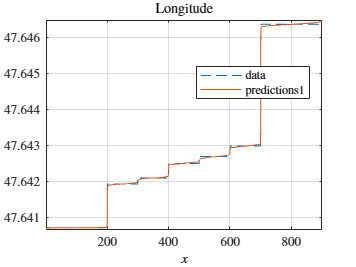

fiv = 10;
for i = 1
    % :l/2
    figure;
    r = 1; co = 1; t = tc{r,co};
    plot(sort(t(:, end).Variables/fiv^rem(co,2) ...
        ),'--');
    xlabel('$x$','interpreter','latex'); axis tight
    axe(); hold on;
    plot(sort(predict(gtc{r,co},t(:, 1:end-1 ...
        ).Variables)/fiv))
    % plot(predict(gt{r,co},t(:, 1:end-1 ...
    % ).Variables)/f)
    hold off; grid on; % xline(I)
    legend({'data','predictions1' ...
     % ,'p2' ...
     }, ...
     'Location','Best','interpreter','latex')
    title('Longitude','interpreter','latex')
end

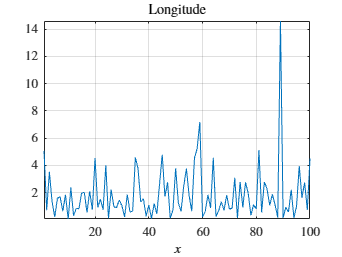

% fiv = 1;
for i = 1
    % :l/2
    figure;
    % r = 2; co = 2; t = nrt{r,co};
    plot(k);
    % plot(sort(t(:, end).Variables/fiv),'--');
    xlabel('$x$','interpreter','latex'); axis tight
    axe();
    % hold on;
    % plot(sort(predict(gc{r,co},t(:, 1:end-1 ...
    %     ).Variables)/fiv))
    % plot(predict(gt{r,co},t(:, 1:end-1 ...
    % ).Variables)/f)
    % hold off;
    grid on; % xline(I)
    % legend({'data','predictions1' ...
     % ,'p2' ...
     % }, ...
     % 'Location','Best','interpreter','latex')
    title('Longitude','interpreter','latex')
end